# Sensitivity Analysis

# Initial Analysis

Author: Edgar Hernandez

>>setup    % Run in command window from /dbf_2026

sens = -1:0.1:1; n = 50;

## Overview of missions

Each mission has a time window of five minutes, starting from throttle up to crossing of finish line (not including landing).

Each mission has distinct payloads

- Mission One: No payload

- Mission Two: Passengeres and cargo payload

- Mission Three: Externally stowed banner and banner deplyoment system

### Mission One

Regular flight mission

M1_max = 1

M1_max = 1

### Mission Two

Charter Flight - payload of passengers and cargo

***Scoring Criteria***

$M_2 =1+\frac{N_{\textrm{net}-\textrm{income}} }{{\textrm{MAX}}_{\textrm{net}-\textrm{income}} }$, where MAX is the highest net income score of all teams


$$\textrm{Net}\;\textrm{Income}=\textrm{Income}-\textrm{Cost}$$



$$\textrm{Income}=n_{\textrm{passengers}} *\left(l_{\textrm{p1}} +\left(l_{\textrm{p2}} \cdot n_{\textrm{laps}} \right)\right)+n_{\textrm{cargo}} \cdot \left(l_{\textrm{c1}} +\left(l_{\textrm{c2}} *n_{\textrm{laps}} \right)\right)$$



$$\textrm{Cost}=n_{\textrm{laps}} \cdot \left(C_e +\left(n_{\textrm{passengers}} \cdot C_p \right)+\left(n_{\textrm{cargo}} \cdot C_c \right.\right)\cdot \textrm{EF}$$


$\textrm{EF}=\frac{E_{\textrm{battery}} }{100}$, where Ebattery is the sum of energies of propulsion batteries in W-hrs

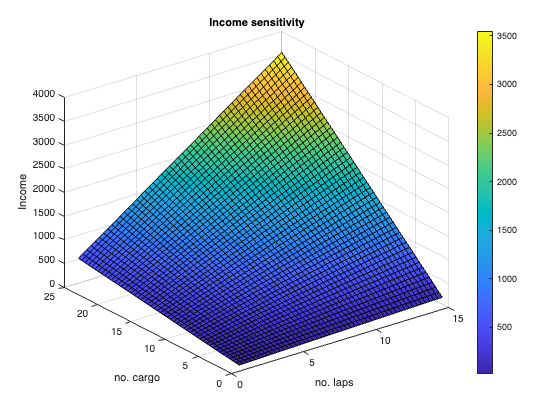

% constants
lp1 = 6; lp2 = 2; lc1 = 10; lc2 = 8;
ce = 10; cp = 0.5; cc = 2;

% Control
EF = 1;
n_lap_vector = linspace(1, 15, n);
n_cargo_vector = linspace(1, 25, n);
e_battery_vector = linspace(25, 100, n);

% Observe sensitivity between income and cost
[Nlaps, Ncargo] = meshgrid(n_lap_vector, n_cargo_vector);
income_vector = Ncargo/3.*(lp1+(lp2.*Nlaps)) + Ncargo.*(lc1+(lc2.*Nlaps));
cost_vector = Nlaps.*(ce+(Ncargo/3.*cp)) + (Ncargo*cc).*EF;

income_fig = figure(); title('Income sensitivity')
surface(Nlaps, Ncargo, income_vector); view(3); colorbar(); grid('on')
xlabel('no. laps'); ylabel('no. cargo'); zlabel('Income')

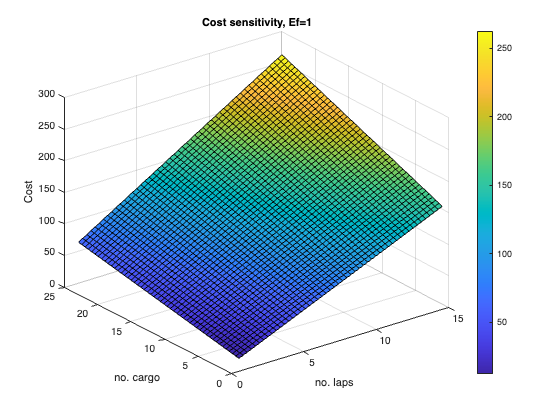

cost_fig = figure(); cost_title = 'Cost sensitivity, Ef='+ string(EF); title(cost_title)
surface(Nlaps, Ncargo, cost_vector); view(3); colorbar(); grid('on')
xlabel('no. laps'); ylabel('no. cargo'); zlabel('Cost')

### Mission Three

Banner Flight - payload of banner 


$$M_3 =2+\frac{N\left(\frac{n_{\textrm{laps}} *l_{\textrm{banner}} }{\textrm{RAC}}\right)}{\textrm{Max}\left(\frac{n_{\textrm{laps}} *l_{\textrm{banner}} }{\textrm{RAC}}\right)}$$



$$\textrm{RAC}=0\ldotp 05*\textrm{WS}+0\ldotp 75$$


b/c RAC only varies by 10%, do analysis with max WS (5"), RAC=1

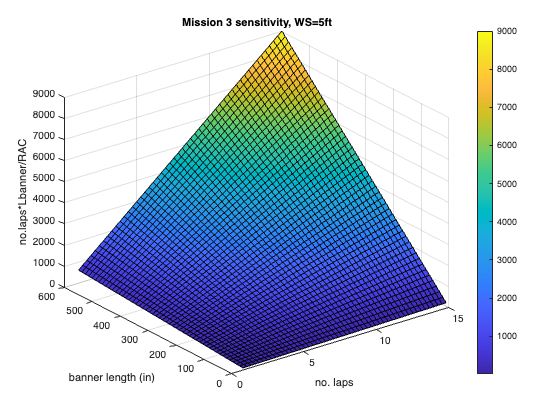

l_banner_vector = linspace(10, 600, n);

[Nlaps, Lbanner] = meshgrid(n_lap_vector, l_banner_vector);
N_m3_vector = Nlaps.*Lbanner;

m3_fig = figure(); title('Mission 3 sensitivity, WS=5ft')
surface(Nlaps, Lbanner, N_m3_vector); view(3); colorbar(); grid('on')
xlabel('no. laps'); ylabel('banner length (in)'); zlabel('no.laps*Lbanner/RAC')

# Total Scoring Analysis

This analysis aims to combine all previous sensitivity analysis. Where the total mission score is observed, instead of their costs functions

clear; n = pi^2;
energy_vector = linspace(20, 100, n);
cargo_vector = linspace(1, 5, n);
passengers_vector = linspace(10, 50, n);
laps_vector = linspace(1, 10, n);
banner_length_vector = linspace(250, 500, n);
wingspan_vector = linspace(3, 5, n);


$$\textrm{Total}\;\textrm{Mission}\;\textrm{Score}=M_1 +M_2 +M_3 +\textrm{GM}$$



$$\textrm{Total}\;\textrm{Mission}\;\textrm{Score}=1+1+\frac{N\left(6n_p +10n_c +n_l \left(2n_p +8n_c \right)-\frac{E*n_l }{100}\left(10+0\ldotp 5n_p +2n_c \right)\right)}{\max \left(6n_p +10n_c +n_l \left(2n_p +8n_c \right)-\frac{E*n_l }{100}\left(10+0\ldotp 5n_p +2n_c \right)\right)}+2+\frac{N\left(\frac{n_l *L_b }{0\ldotp 05b_{\textrm{wing}} +0\ldotp 75}\right)}{\max \left(\frac{n_l *L_b }{0\ldotp 05b_{\textrm{wing}} +0\ldotp 75}\right)}+\frac{t_{\min } }{t_n }$$


assuming max scores found in best_mission_scores.mlx:

- 
$$\max \left(\textrm{net}-\textrm{income}\right)=4000$$


- 
$$\max \left(M_3 -\textrm{cost}\right)=3000$$


- 
$$t_{\min } =12\;\textrm{seconds}$$


The total scoring function gets narrowed down to:

$\mathrm{Total}\;\mathrm{Mission}\;\mathrm{Score}=4+\frac{6n_p +10n_c +n_{l,2} \left(2n_p +8n_c \right)-\frac{E*n_{l,2} }{100}\left(10+0\ldotp 5n_p +2n_c \right)}{4000}+\frac{n_{l,3} *L_b }{3000\left(0\ldotp 05b_{\mathrm{wing}} +0\ldotp 75\right)}+\frac{12}{t_n }$, where t is measured in seconds, L is in inches, and b is in feet

## Overall Sensitivities:

Observing how total score changes by fixing some values and changing others. Try plotting slices of surfaces on same figures?

### Varying Cargo, Pasengers, and M2 laps:

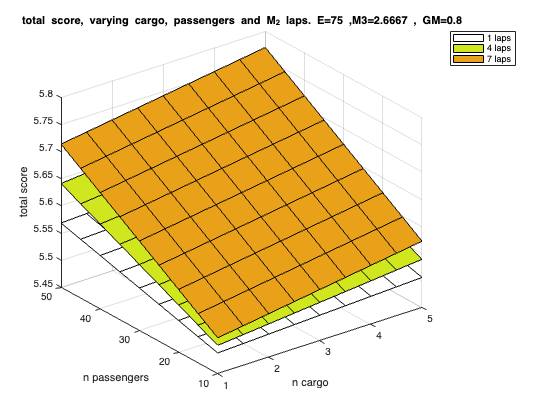

sens.laps.n_slices = 3;
sens.laps.min = 1; 
sens.laps.max = 7;
sens.laps.nl2_vector = linspace(sens.laps.min, sens.laps.max, sens.laps.n_slices);
sens.laps.E = 75; 
sens.laps.nl3 = 5;
sens.laps.L = 400;
sens.laps.b = 5;
sens.laps.t = 15;
sens.laps.m3 = 2 + min(sens.laps.nl3*sens.laps.L/3000/(0.05*sens.laps.b+0.75), 1);
sens.laps.gm = min(12/sens.laps.t, 1);

temp_title = 'total score, varying cargo, passengers and M_2 laps. E='+string(sens.laps.E)+' ,M3='+string(sens.laps.m3)+' , GM='+string(sens.laps.gm);
[C, P] = meshgrid(cargo_vector, passengers_vector);
sens.laps.fig = figure(); labels = strings(1, length(sens.laps.nl2_vector));
for i = 1:sens.laps.n_slices
    temp_nl2 = sens.laps.nl2_vector(i);
    % temp_m2 = 1/5733*(6*P+10*C+temp_nl2*(2*P+8*C)-sens.laps.E*temp_nl2/100*(10+0.05*P+2*C));
    temp_m2 = 1/4000*(6*P+10*C+temp_nl2*(2*P+8*C)-sens.laps.E*temp_nl2/100*(10+0.05*P+2*C));% new max net-income
    temp_m2 = 1 + min(temp_m2, 1);
    temp_total_score = 1+temp_m2+sens.laps.m3+sens.laps.gm;
    if i > 1
        hold on; surface(C, P, temp_total_score, FaceColor=rand(1, 3)); hold off;
    else
        surface(C, P, temp_total_score, FaceColor="w")
    end
    labels(i) = string(temp_nl2) + ' laps';
end
view(3); grid('on'); legend(labels); xlabel('n cargo'); ylabel('n passengers'); zlabel('total score'); title(temp_title);

### Varying passengers, M2 laps, and Energy:

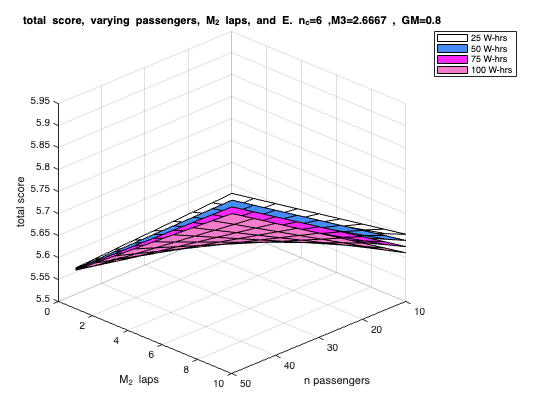

sens.energy.n_slices = 4;
sens.energy.min = 25; 
sens.energy.max = 100;
sens.energy.E_vector = linspace(sens.energy.min, sens.energy.max, sens.energy.n_slices);
sens.energy.nc = 6; 
sens.energy.nl3 = 5;
sens.energy.L = 400;
sens.energy.b = 5;
sens.energy.t = 15;
sens.energy.m3 = 2 + min(sens.energy.nl3*sens.energy.L/3000/(0.05*sens.energy.b+0.75), 1);
sens.energy.gm = min(12/sens.energy.t, 1);

temp_title = 'total score, varying passengers, M_2 laps, and E. n_c='+string(sens.energy.nc)+' ,M3='+string(sens.energy.m3)+' , GM='+string(sens.energy.gm);
[P, Nl] = meshgrid(passengers_vector, laps_vector);
sens.energy.fig = figure(); labels = strings(1, length(sens.energy.E_vector));
for i = 1:sens.energy.n_slices
    temp_E = sens.energy.E_vector(i);
    % temp_m2 = 1/5733*(6*P+10*sens.energy.nc+Nl.*(2*P+8*sens.energy.nc) - temp_E*Nl/100.*(10+0.05*P+2*sens.energy.nc));
    temp_m2 = 1/4000*(6*P+10*sens.energy.nc+Nl.*(2*P+8*sens.energy.nc) - temp_E*Nl/100.*(10+0.05*P+2*sens.energy.nc));% new max net-income
    temp_m2 = 1 + min(max(temp_m2, 0), 1);
    temp_total_score = 1+temp_m2+sens.energy.m3+sens.energy.gm;
    if i > 1
        hold on; surface(P, Nl, temp_total_score, FaceColor=rand(1, 3)); hold off;
    else
        surface(P, Nl, temp_total_score, FaceColor="w")
    end
    labels(i) = string(temp_E) + ' W-hrs';
end
view([-225, 27.5]); grid('on'); legend(labels); xlabel('n passengers'); ylabel('M_2 laps'); zlabel('total score'); title(temp_title);

### Varying M3 laps, banner length, and wingspan

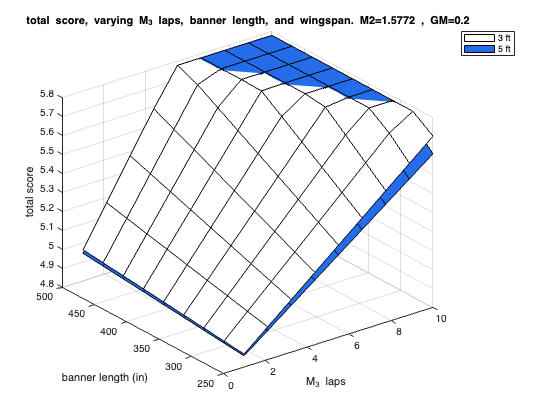

sens.bwing.n_slices = 2; 
sens.bwing.min = 3; 
sens.bwing.max = 5;
sens.bwing.bwing_vector = linspace(sens.bwing.min, sens.bwing.max, sens.bwing.n_slices);
sens.bwing.np = 100; 
sens.bwing.nc = 12;
sens.bwing.nl2 = 6;
sens.bwing.E = 80;
sens.bwing.t = 60;
sens.bwing.m2 = 1 + 1/4000*(6*sens.bwing.np+10*sens.bwing.nc+sens.bwing.nl2*(2*sens.bwing.np+8*sens.bwing.nc) - ...
    sens.bwing.E*sens.bwing.nl2/100.*(10+0.05*sens.bwing.np+2*sens.bwing.nc)); % new max net-income
sens.bwing.gm = min(12/sens.bwing.t, 1);

sens.bwing.title = 'total score, varying M_3 laps, banner length, and wingspan. M2='+string(sens.bwing.m2)+' , GM='+string(sens.bwing.gm);
[Nl, L] = meshgrid(laps_vector, banner_length_vector);
sens.bwing.fig = figure(); sens.bwing.labels = strings(1, length(sens.bwing.bwing_vector));
for i = 1:sens.bwing.n_slices
    temp_b = sens.bwing.bwing_vector(i);
    temp_m3 = Nl.*L/3000/(0.05*temp_b+0.75);
    temp_m3 = 2 + min(temp_m3, 1);
    temp_total_score = 1+sens.bwing.m2+temp_m3+sens.bwing.gm;
    if i > 1
        hold on; surface(Nl, L, temp_total_score, FaceColor=rand(1, 3)); hold off;
    else
        surface(Nl, L, temp_total_score, FaceColor="w")
    end
    sens.bwing.labels(i) = string(temp_b) + ' ft';
end
view(3); grid('on'); legend(sens.bwing.labels); xlabel('M_3 laps'); ylabel('banner length (in)'); zlabel('total score'); title(sens.bwing.title);

### Varying M3 laps, banner length, and passengers

#### normal model

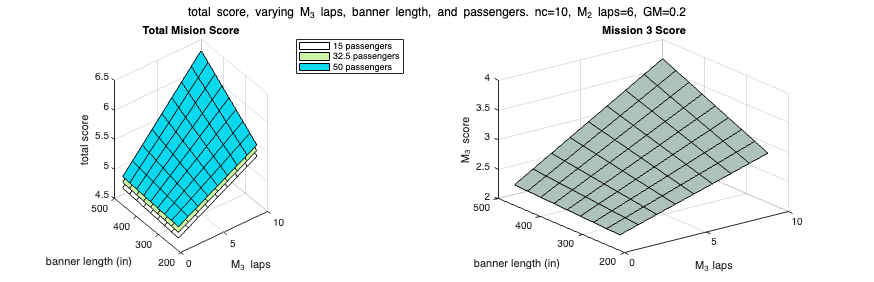

Mission two scores: 
    1.2458    1.3421    1.4383


sens.np.n_slices = 3; 
sens.np.min = 15; 
sens.np.max = 50;
sens.np.np_vector = linspace(sens.np.min, sens.np.max, sens.np.n_slices);
sens.np.nc = 10; 
sens.np.nl2 = 6;
sens.np.E = 50;
sens.np.b = 5;
sens.np.t = 60;

sens.np.gm = min(12/sens.np.t, 1);
sens.np.rac = 0.05*sens.np.b + 0.75;

sens.np.title = 'total score, varying M_3 laps, banner length, and passengers. nc='+string(sens.np.nc)+', M_2 laps='+string(sens.np.nl2)+', GM='+string(sens.np.gm);

sens.np.m3 =2 + min(Nl.*L/3000/(sens.np.rac), 2);

[Nl, L] = meshgrid(laps_vector, banner_length_vector);
sens.np.fig = figure(Position=[680 458 1300 420]); sens.np.labels = strings(1, length(sens.np.np_vector));
subplot(1, 2, 1)
for i = 1:sens.np.n_slices
    temp_np = sens.np.np_vector(i);

    temp_m2 = 1 + 1/3000*(6*temp_np+10*sens.np.nc+sens.np.nl2*(2*temp_np+8*sens.np.nc) - ...
        sens.np.E*sens.np.nl2/100*(10+0.5*temp_np+2*sens.np.nc));

    temp_total_score = 1+temp_m2+sens.np.m3+sens.np.gm;
    if i > 1
        hold on; surface(Nl, L, temp_total_score, FaceColor=rand(1, 3)); hold off
    else
        surface(Nl, L, temp_total_score, FaceColor="w")
    end
    sens.np.m2(i) = temp_m2;
    sens.np.labels(i) = string(temp_np) + ' passengers';
end
view(3); grid('on'); legend(sens.np.labels); xlabel('M_3 laps'); ylabel('banner length (in)'); zlabel('total score'); title('Total Mision Score')
subplot(1, 2, 2); surface(Nl, L, sens.np.m3, FaceColor=rand(1,3)); view(3); grid('on'); title('Mission 3 Score'); xlabel('M_3_ laps'); ylabel('banner length (in)'); zlabel('M_3 score')
sgtitle(sens.np.title); fprintf('Mission two scores: \n'); disp(sens.np.m2)

#### Passenger dependant GM model 

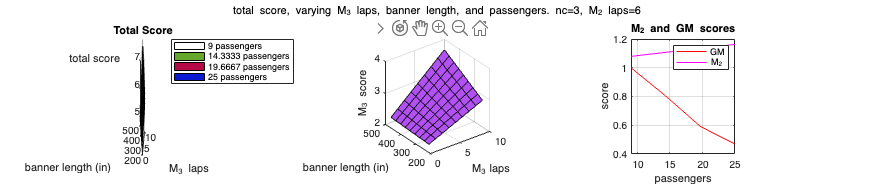

sens.np.n_slices = 4; 
sens.np.min = 9; 
sens.np.max = 25;
sens.np.np_vector = linspace(sens.np.min, sens.np.max, sens.np.n_slices);
sens.np.nc = 3; 
sens.np.nl2 = 6;
sens.np.E = 80;
sens.np.b = 5;

sens.np.title = 'total score, varying M_3 laps, banner length, and passengers. nc='+string(sens.np.nc)+', M_2 laps='+string(sens.np.nl2);

sens.np.rac = 0.05*sens.np.b + 0.75;
[Nl, L] = meshgrid(laps_vector, banner_length_vector);
sens.np.m3 =2 + min(Nl.*L/3000/(sens.np.rac), 2);
sens.np.gm = ones(1, length(sens.np.np_vector));

sens.np.fig = figure(Position=[680 458 2000 420]); sens.np.labels = strings(1, length(sens.np.np_vector)); 
subplot(1, 3, 1)
for i = 1:sens.np.n_slices
    temp_np = sens.np.np_vector(i);

    temp_m2 = 1 + 1/3000*(6*temp_np+10*sens.np.nc+sens.np.nl2*(2*temp_np+8*sens.np.nc) - ...
        sens.np.E*sens.np.nl2/100*(10+0.5*temp_np+2*sens.np.nc));
    temp_gm = min(12/(temp_np+sens.np.nc/5), 1);
    temp_total_score = 1+temp_m2+sens.np.m3+temp_gm;
    if i > 1
        hold on; surface(Nl, L, temp_total_score, FaceColor=rand(1, 3)); hold off
    else
        surface(Nl, L, temp_total_score, FaceColor="w")
    end
    sens.np.m2(i) = temp_m2;
    sens.np.gm(i) = temp_gm;
    sens.np.labels(i) = string(temp_np) + ' passengers';
end
view(3); grid('on'); legend(sens.np.labels); xlabel('M_3 laps'); ylabel('banner length (in)'); zlabel('total score'); title('Total Score')
subplot(1, 3, 2); surface(Nl, L, sens.np.m3, FaceColor=rand(1,3)); view(3); grid('on'); title('Mission 3 Score'); xlabel('M_3_ laps'); ylabel('banner length (in)'); zlabel('M_3 score')
subplot(1, 3, 3); plot(sens.np.np_vector, sens.np.gm, Color='r'); grid('on'); xlabel('passengers'); ylabel('score'); title('M_2 and GM scores');
hold on; plot(sens.np.np_vector, sens.np.m2, Color='m'); legend('GM', 'M_2')
sgtitle(sens.np.title);

## Conditional Sensitivities:

Observe the change in the sensitivity with changing percent values, starting at 0%

Use the same known value to observe change

sens = -1:0.1:1;

### Laps (M2) sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(n_{l,2} \right)}=\frac{1}{5733}\left(\frac{E}{10}+n_p \left(2+\frac{E}{200}\right)+n_c \left(8+\frac{E}{50}\right)\right)$$


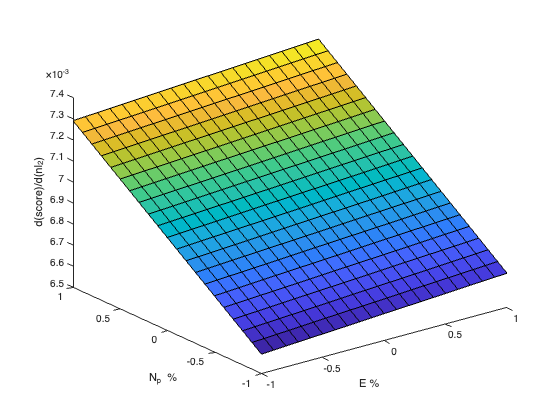

[dE, dNp] = meshgrid(sens, sens);
temp_nc = 5;
d_score_d_nl2 = 1/5733*(dE/10+dNp.*(2+dE/200)+temp_nc*(8+dE/50));
fig = figure();
surface(dE, dNp, d_score_d_nl2); title = 'd(Score)/d(nl2) w/ nc='+string(temp_nc); view(3)
xlabel('E %'); ylabel('N_p %'); zlabel('d(score)/d(nl_2)')

### Passengers sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(n_p \right)}=\frac{1}{5733}\left(6+n_{l,2} \left(-\frac{E}{200}+2\right)\right)$$


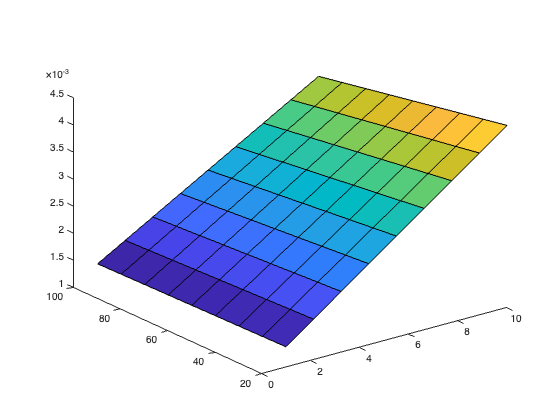

[N, E] = meshgrid(laps_vector, energy_vector);
np_sens_vector = 1/5733*(6+N.*(-E/200+2));
np_fig = figure();
surface(N, E, np_sens_vector); view(3)

### Cargo Sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(n_c \right)}=\frac{1}{5733}\left(10+n_{l,2} \left(-\frac{E}{50}+8\right)\right)$$


% [N, E] = meshgrid(laps_vector, energy_vector);
nc_sens_vector = 1/5733*(10+N.*(-E/50+8));
nc_fig = figure();
surface(N, E, np_sens_vector); view(3)

### Energy Sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(E\right)}=\frac{1}{5733}\left(-\frac{n_{l,2} }{100}\left(10+0\ldotp 5n_p +2n_c \right)\right)$$


### Laps (M3) sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(n_{l,3} \right)}=\frac{L_b }{3000\left(0\ldotp 05b_{\textrm{wing}} +0\ldotp 75\right)}$$


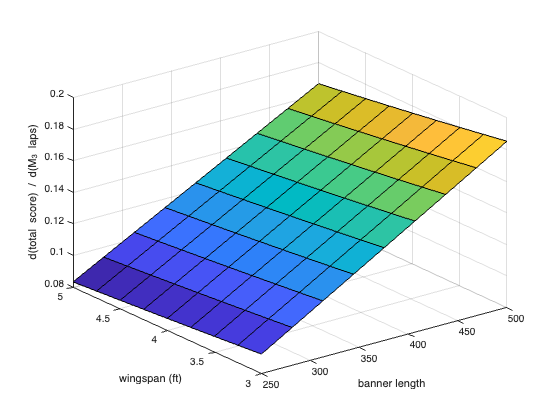

[L, B] = meshgrid(banner_length_vector, wingspan_vector);
nl3_sens_vector = 1/3000*L./(0.05*B+0.75);
nl3_fig = figure();
surface(L, B, nl3_sens_vector); view(3)
xlabel('banner length'); ylabel('wingspan (ft)'); zlabel('d(total score) / d(M_3 laps)'); grid('on')

### Banner Length Sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(L_b \right)}=\frac{n_{l,3} }{3000\left(0\ldotp 05b_{\textrm{wing}} +0\ldotp 75\right)}$$


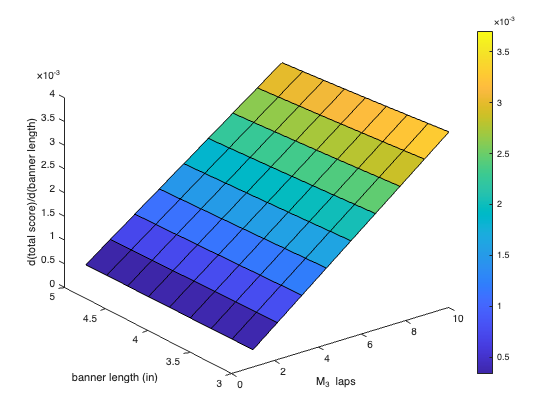

[N, B] = meshgrid(laps_vector, wingspan_vector);
lb_sens_vector = 1/3000*N./(0.05*B+0.75);
lb_fig = figure();
surface(N, B, lb_sens_vector); view(3); colorbar()
xlabel('M_3 laps'); ylabel('banner length (in)'); zlabel('d(total score)/d(banner length)')

### Wingspan Sensitivity:


$$\frac{\delta \left(\textrm{Score}\right)}{\delta \left(b_{\textrm{wing}} \right)}=\frac{1}{3000}\left(-\frac{0\ldotp 05n_{l,3} L_b }{0\ldotp 05b+0\ldotp 75}\right)$$
